# Computer Vision - Laboratory 9: Video segmentation

**Authors**: Emer Rodriguez Formisano and Jorge Alexander

**Date**: 11/12/2017

## 9.1 Background substraction

The laboratory definition and the theory slides explain the process of background subtraction which is going to be applied next. The first step is to load the video file.

v = VideoReader('./Barcelona.mp4');

**A) Find where one scene ends and another begins (i.e. the wvideo shots). What measure of the images can you use to distinguish the scenes? **

There are several approaches for shot detection such as pixel comparison, block-based approach, edge change ratio and Histogram Comparison. The later method was used which tries to identify cuts by checking abrupt changes in the frame histograms. If the change exceeds a threshold, then a cut is considered. The function `getframedifferences` implements the method, the code computes the RGB histograms for each frame and the differences between them are measured by using the eucledian norm. The returned object is a vector of the distances if a video object is given as an input.

dist = getframedifferences(v);

The distances are then passed to a function named `getscenestarttime `which finds the best possible cuts obtained using a fixed threshold. Code contains the true index vector of cuts hardcoded and it implements an iterative process that checks how close an index vector of cuts from a given percentile is to the true index vector using the Jaccard coefficient. The function returns the best percentile and its Jaccard coefficient as a "goodness of fit".

cuts_start_frame = getscenestarttime(dist);

Best percentile: 0.97648 with Jaccard: 0.71014


In practice, the true index of cuts will not be available, so a fixed threshold should be set by the expert, using the distance chart, if the fixed threshold approach is choosen. However, this exercise was done in order to measure what is the best performance we can obtain by using a fix threshold if the true cuts are known. The obtained Jaccard coefficient is not bad but an adaptive threshold using windows could probably improve it.

The following plot summaries the computed distances together with the threshold selected.

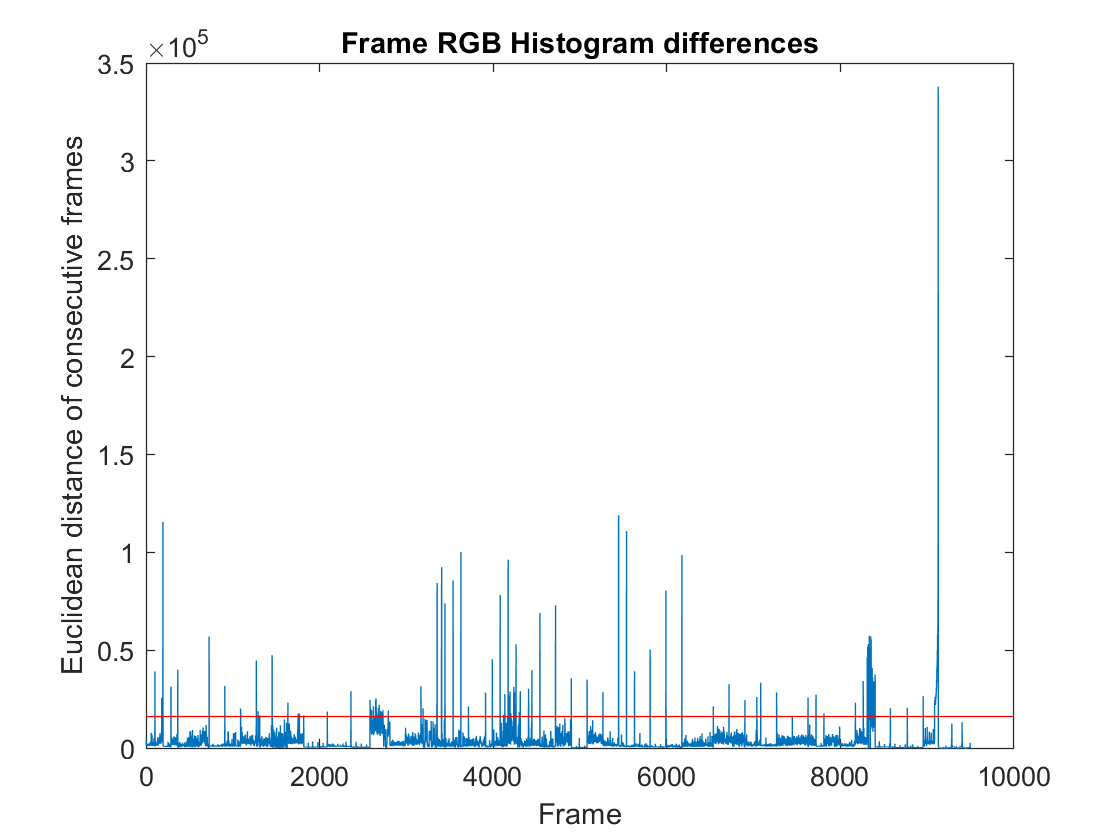

dist_ref = quantile(dist, 0.97648);
plot(dist), title("Frame RGB Histogram differences");
xlabel("Frame"), ylabel("Euclidean distance of consecutive frames");
hline = refline([0 dist_ref]);
hline.Color = 'r';

Note how the threshold line crosses some noisy zones with high density of pikes. This leads to some false positive cuts but those were reduced by adding a simple rule: cuts with less than a second (FrameBuffer) were not considered.

**B) Apply a background subtraction algorithm (e.g. the median filter to detect the static scene forming the background).**

The implementation is divided in two parts. The first part is done by the `getscenematrix` function that has as imports the video object, the starting frame index of the video segment and its length.  The code creates a 4D (Height, Width, Channel, Time) matrix which contains the RGB frame values for each timestep (25 frames per second). The background frame is computed using the median in dimension 4 (Time) which is then used to compute the foreground RGB frames by substracting the frame to each timestep. Thus, the function returns 3 elements: the segmented video as a matrix of frames, the background frame and the foreground video as a matrix of frames.

The second part of the implementation is to repeat the part one process for each cut or segment of video detected in the previous section. The following code does the iterative process and accumulates the frames for the first cuts for illustrative purposes. 

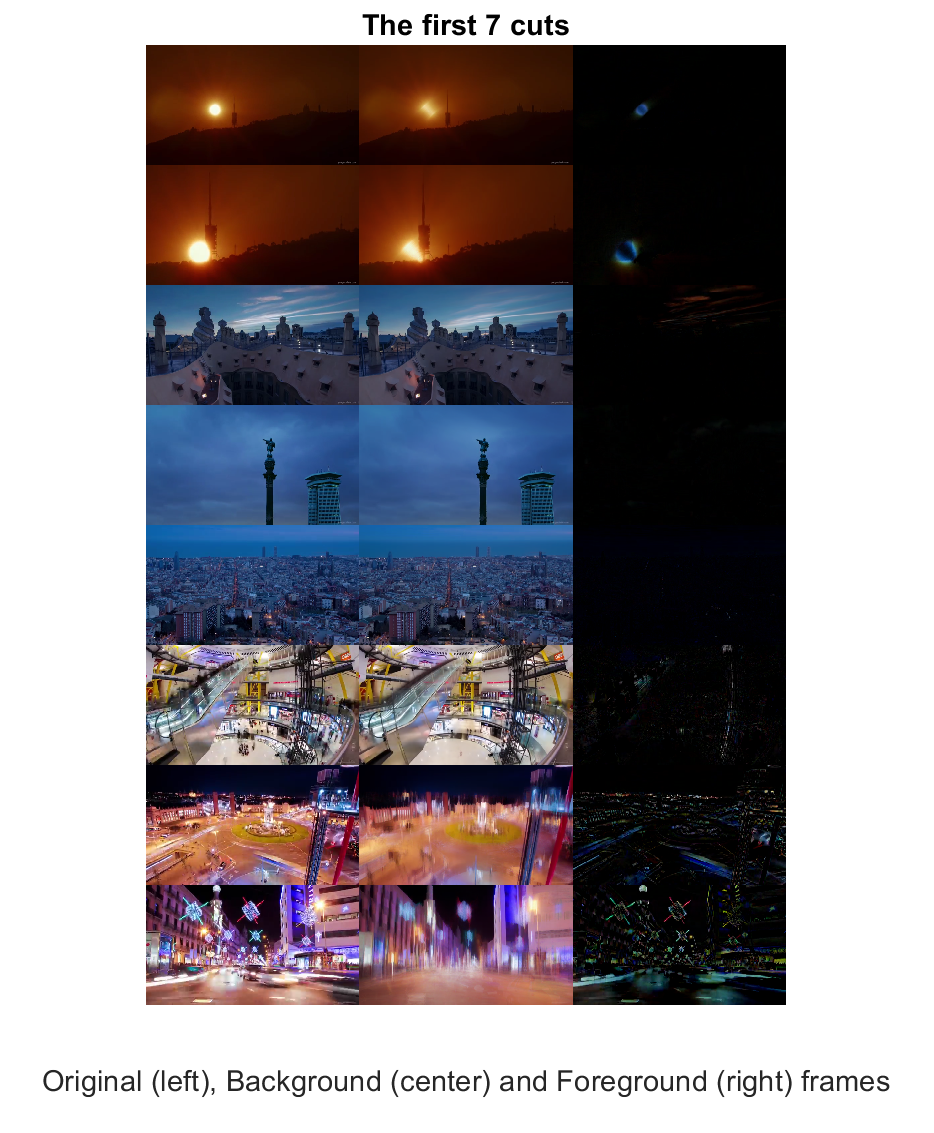

%% Apply the background substraction to each cut
samples = [];
for i = 1:length(cuts_start_frame)-1
    [video_frames, bg_frame, fg_video] = getscenematrix( ...
        v, cuts_start_frame(i), diff(cuts_start_frame(i:i+1))-1);    
    middle_idx = max([1, floor(size(video_frames,4)/2)]);
    
    % Report results
    %implay(video_frames)
    %implay(fg_video)
    frame = video_frames(:,:,:,middle_idx);
    fg_frame = fg_video(:,:,:,middle_idx);
    
    row_samples = [frame bg_frame fg_frame];
    %imshow(row_samples)
    %w = waitforbuttonpress;
    if i < 9
        samples = [samples; row_samples];
    end
end
imshow(samples), title("The first 7 cuts"), ...
    xlabel("Original (left), Background (center) and Foreground (right) frames")

As the background frame is computed using the median, it can be seen as an enhanced average frame less sensitive to the changes. It represent the stable pixels, those that does not change during the cut. If such information is substracted in each frame of the cut, we will have a dark picture which highlights the pixels that tend to change over time. 

In the first two cuts of the Barcelona movie, the pixels that were highlighted the most were those that belong to the sun as it the main object that moves during the scene. In the following pair of cuts, the foreground frames are dark because just a few pixels changes, mostly the ones that belong to the clouds or the sky. In the last 2 cuts, the pixels that move belongs to the cars and the people that are moving during the shots. Specially the moving lights.

The disadvantages of the proposed method are that it is sensitive to the correctness and quality of the cuts and it works mostly for static camera shots only. If the segment is poorly cut, the estimation of the median frame (background) can be impacted. If the segment has a moving camara, then it becomes hard to distinguish if the pixels are changing due to the camara or due to the object itself.

The techinique is quite useful for surveillance as the CCTV cameras are fixed and they are continously on. If the camera can detect the movment, it could automatically start and pausing recording in order to minimize the disk space used for recording. 

The approach could be used for counting elements such as cars going through in a payroll. Probably, the substracted background images should have to be binarised in order to clearly identify the shapes/objects.

**[OPTIONAL] Apply the algorithm on another video you can find in internet.**

The video of a functioning Wind Turbine was proposed for background substraction as it will clearly show what parts are moving (foreground) from the static ones (background).

The following images shows the results. The first contain the original image, while the second is the background frame and the third is the difference between the first two.

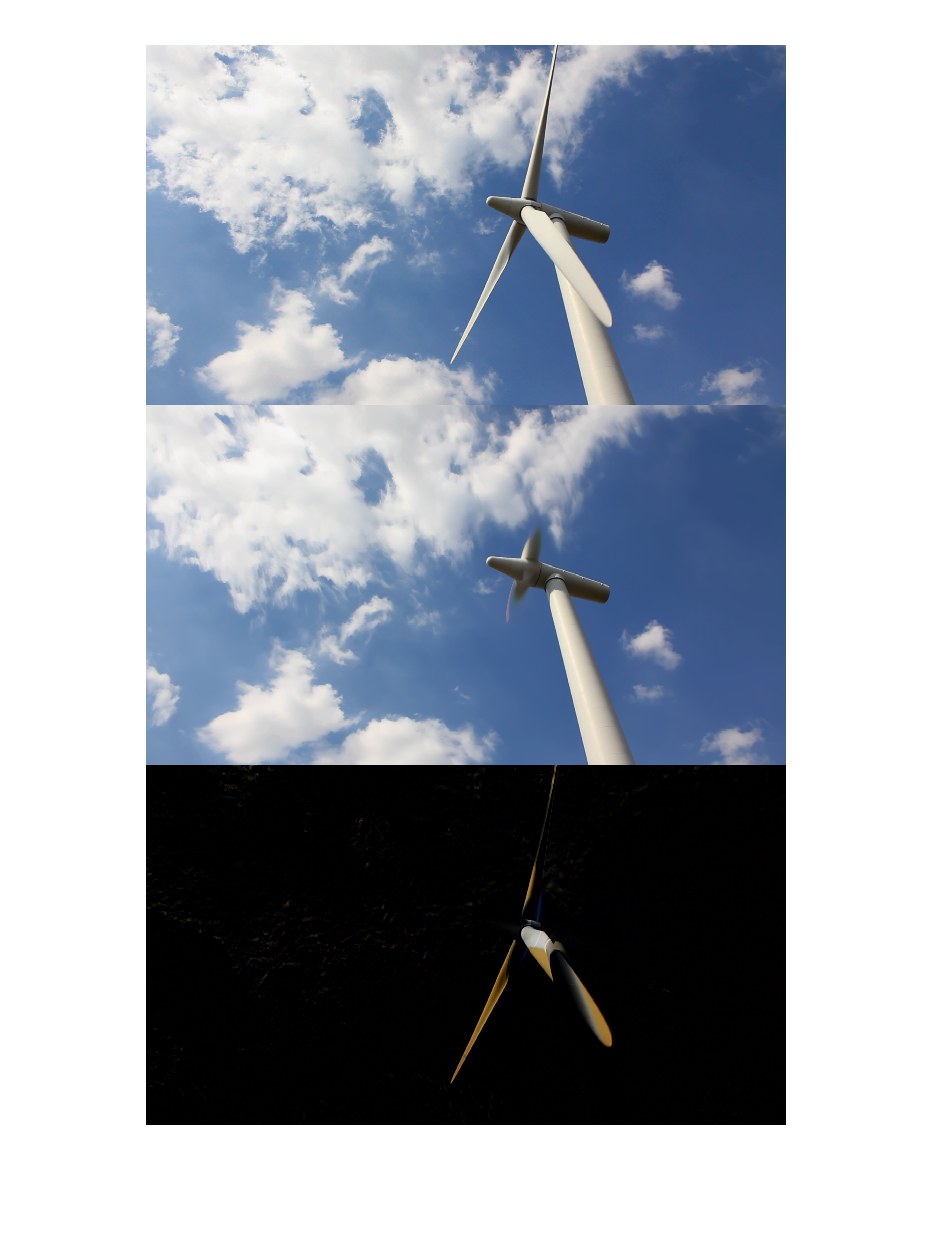

vwt = VideoReader('./windturbine.mov');
[vwt_frames, vwt_bg_frame, vwt_fg_video] = getscenematrix(vwt, 1, 381);
imshow([vwt_frames(:,:,:,190); vwt_bg_frame; vwt_fg_video(:,:,:,190)]);

The backgorund frame does not contain the blades as they are the main moving parts of the scene. The clouds are perfectly defined as the information is contained in other frames. This is similar to what happends when the "tourist delete button" feature is used. The baldes are clearly defined in the foreground frame and notice how the tower pixels are substracted from the moving blade because the tower is considered background. 

The following code line shows the foreground movie not available in the PDF report. 

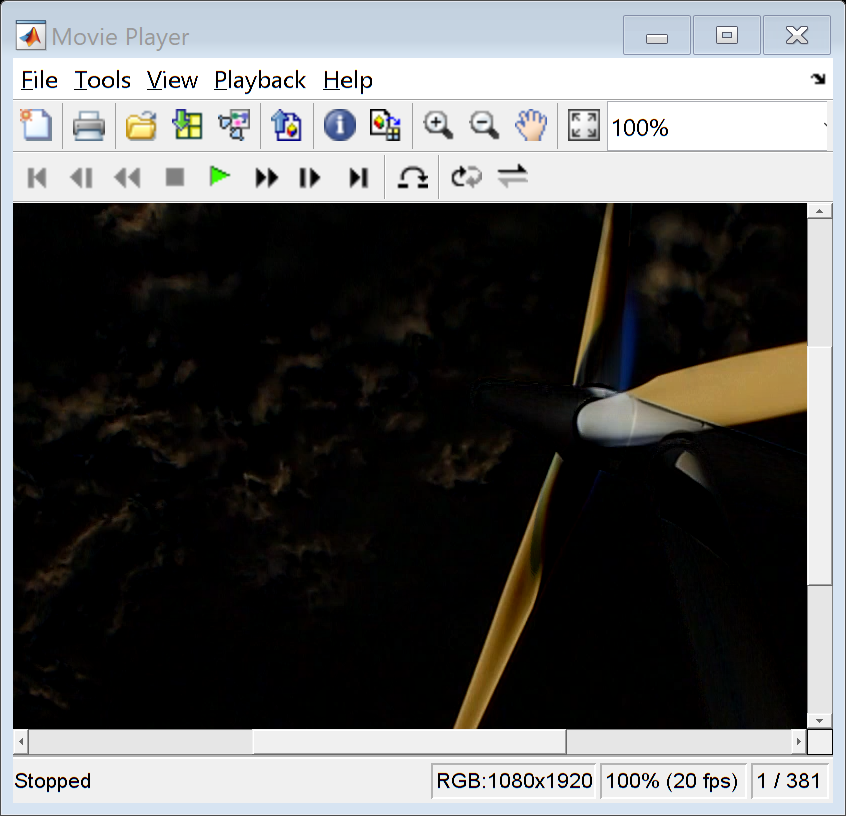

implay(vwt_fg_video)

Resource: https://www.videvo.net/video/wind-turbine-5/207/

## Functions

function dist = getframedifferences(v)
    % Function computes the histogram differences of consecutive frames
    num_frames = floor(v.Duration*v.FrameRate);
    dist = zeros(num_frames - 1, 1);
    idx = 1;
    prev_hist = imagehist(readFrame(v));

    while hasFrame(v)    
        frame = readFrame(v);
        curr_hist = imagehist(frame);
        dist(idx) = norm(curr_hist - prev_hist, 2);
        idx = idx + 1;
        prev_hist = curr_hist;
    end
end

function h = imagehist(frame)    
    h = horzcat([imhist(frame(:,:,1)) imhist(frame(:,:,2)) imhist(frame(:,:,3))]);  
end

function start_frame = getscenestarttime(dist)
    % Function finds the threshold and return the index of the starting
    % frame of the cut
    true_start = [104 196 289 367 728 909 1091 1272 1454 ...
        1636 1818 2090 2362 2582 2810 2991 3169 3355 3445 3539 ...
        3629 3716 3913 3991 4081 4173 4264 4447 4539 4719 4901 ...
        4993 5083 5265 5446 5537 5629 5809 5991 6175 6537 6718 ...
        6901 7083 7266 7447 7628 7720 7811 7992 8174 8264 8310 ...
        8355 8401 8577 8772 8955 9129]'; % End 9129 (Black)
    
    % Find a good threshold based on grown truth cuts.
    % Jaccard Coefficient used
    best_diff = 0;    
    for qthres = linspace(0.900, 0.999, 5000)
        thres = quantile(dist, qthres);
        prop_start = find(dist > thres) + 1;
        % Remove credits zone
        prop_start = prop_start(prop_start <= 8955);
        % Remove cuts < 1 second (FrameRate)
        prop_start = prop_start([true; diff(prop_start) > 25]);
        % err = norm(prop_start - true_start, 2);
        jaccoef = length(intersect(true_start, prop_start)) ...
            /length(union(true_start, prop_start));
        if jaccoef > best_diff
            best_diff = jaccoef;
            best_qthres = qthres;
            best_start = prop_start;
        end
    end
    
    disp("Best percentile: " + best_qthres + " with Jaccard: " + best_diff) 
    start_frame = [1; best_start];
    
end

function [video_frames, bg_frame, fg_video] = getscenematrix( ...
    v, start_frame, length_frame)
    % Function that returns the cut's matrix of frames together with
    % the background (median frame) and foreground video (matrix of frames)
    video_frames = zeros(v.Height, v.Width, 3, length_frame, 'uint8');
    if start_frame == 1
     start_ts = 0.0;
    else
     start_ts = start_frame/v.FrameRate;
    end
    v.CurrentTime = start_ts;
    for f = 1:length_frame
     video_frames(:,:,:,f) = readFrame(v);
    end
    % Compute Median frame (background)
    bg_frame = median(video_frames, 4);
    % Substract background (foreground video frames)
    fg_video = video_frames - bg_frame;

end